# Práctica 3: Compensación Gamma

### **Imagen clara**

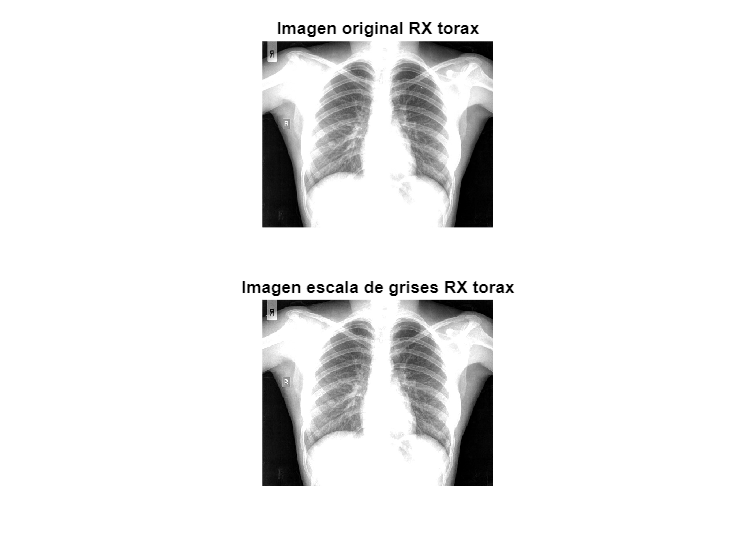

% Cargar imagen
imagen_clara = imread("rx_torax.jpg");

figure;
subplot(2,1, 1)
imshow(imagen_clara)
title("Imagen original RX torax")

subplot(2,1,2)
imagen_clara_rgb = rgb2gray(imagen_clara);
imshow(imagen_clara_rgb)
title("Imagen escala de grises RX torax")

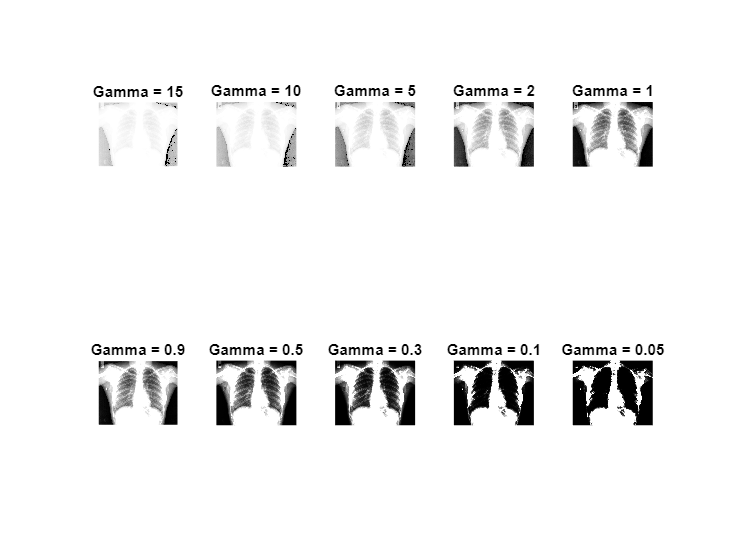


% Aplicación de compesación Gamma
gamma = [15 10 5 2 1 0.9 0.5 0.3 0.1 0.05];

imagen_clara_rgb = double(imagen_clara_rgb);
figure;
for i = 1:length(gamma)
    new_imagen = 255*(imagen_clara_rgb/255).^(1/gamma(i));
    subplot(2, ceil(length(gamma)/2), i);
    imshow(uint8(new_imagen))
    title(['Gamma = ', num2str(gamma(i))])
end

### **Imagen oscura**

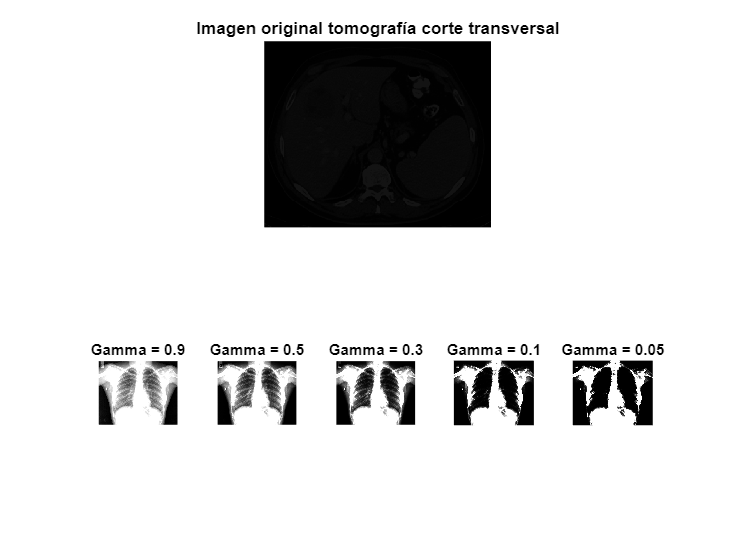

% Cargar imagen
imagen_oscura = imread("tomografia_corte_trans.png");

subplot(2,1,1)
imshow(imagen_oscura)
title("Imagen original tomografía corte transversal")

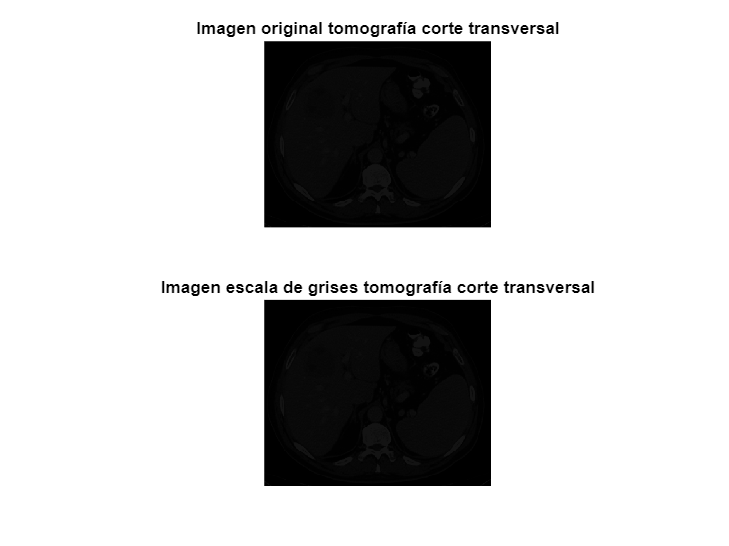


subplot(2,1,2)
imagen_oscura_rgb = rgb2gray(imagen_oscura);
imshow(imagen_oscura_rgb)
title("Imagen escala de grises tomografía corte transversal")

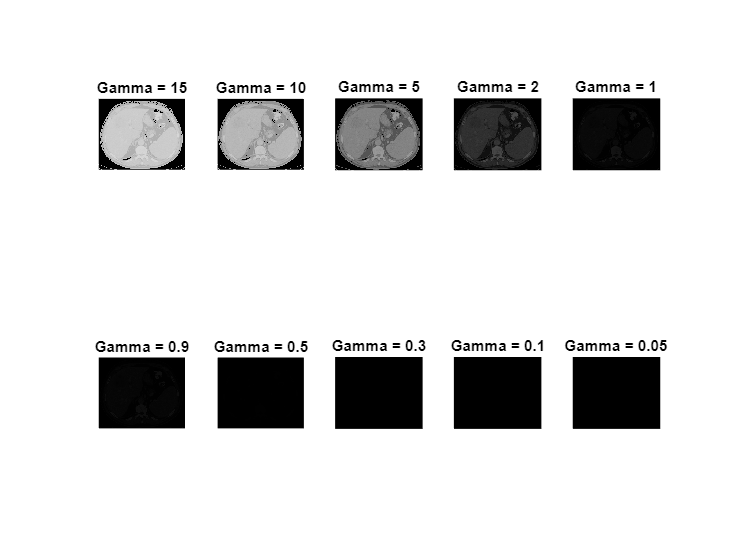


% Aplicación de compesación Gamma
imagen_oscura_rgb = double(imagen_oscura_rgb);
figure;
for i = 1:length(gamma)
    new_imagen = 255*(imagen_oscura_rgb/255).^(1/gamma(i));
    subplot(2, ceil(length(gamma)/2), i);
    imshow(uint8(new_imagen))
    title(['Gamma = ', num2str(gamma(i))])
end